## `Question 01`

`Generate a binary sequence of length L = 1000, considering D 2 f0; 1g and Pr(D = 0) = Pr(D = 1) = 1/2: Use the binary sequence to generate a stream of rectangular pulses of amplitude S, where S belongs to +-A with A = 1.  `

% defining variables

L = 100000;  % binary sequence of length. This value should be change to 100 000 from question 5
A = 1;
miu = 0;
sigma = 1;
tau = 0;

% generating the random bit stream of length L

D = ones(1,L); % create an array of length of ones. dimension = 1 x L

rand = randperm(L, L/2); % generate random indexes with length of half of sequence length  within sequence.
D(rand) = zeros(1, L/2); % replace the D sequence with zeros for random indexes.

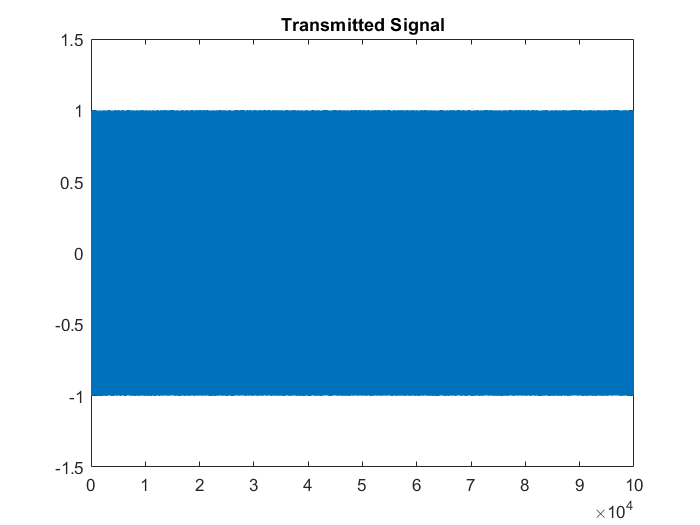

% generate a stream of rectangular pulses

Z = zeros(1, L); % generating a empty zero array as pulse

for index1 = 1:L
    if D(index1) == 1
        S(index1) = A;   % if bit is equal to one assign it as +1
    
    else
        S(index1) = -1 * A;   % if bit is equal to zero assign it as -1
    end
end

% plotting the transmitted signal 
figure;
stairs([1:L], S);
ylim([-1.5 1.5]);
title("Transmitted Signal")

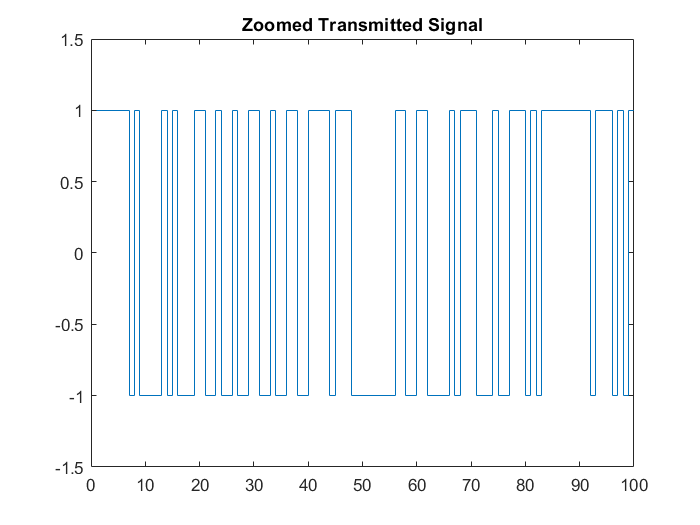


% Zoomed version of Tx Signal
figure;
stairs([1:L], S);
ylim([-1.5 1.5]);
xlim([0 100]);
title("Zoomed Transmitted Signal")

## `Question 02`

`Generate an AWGN sequence, also of length L = 1000, considering ``σ`

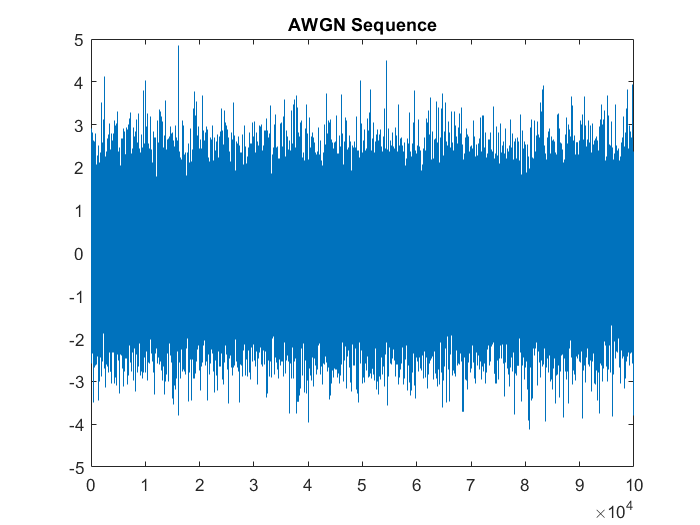

N = miu + sigma*randn(1,L); % generate normal distributed random numbers with mean (miu) and standard deviation (sigma)
figure;
stairs([1:L],N);
title("AWGN Sequence")

## `Question 03`

`Plot the sequence of ``R ``and observe the impact of the variance of noise on  R` `by varying ``σ``2 .`

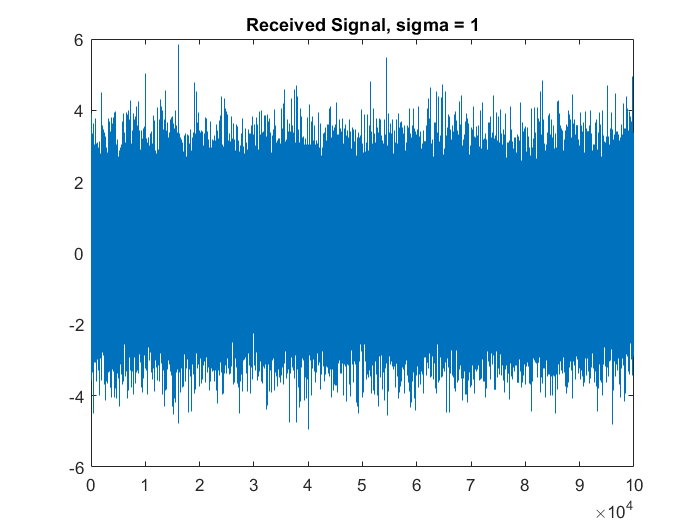

R = S + N; %  add AWGN to the Tx signal 

figure; % plot the Received signal
stairs([1:L],R);
title("Received Signal, sigma = 1")

## `Question 04`

`Sketch and compare the sequence of ``Y ``with the transmitted signal.  `

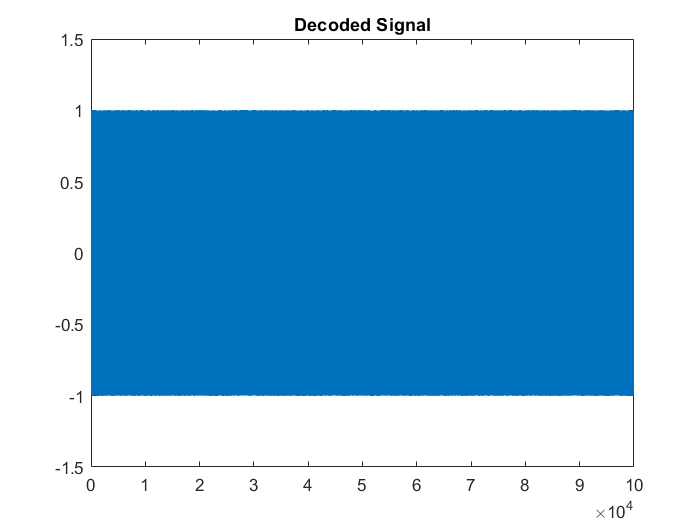

% generate a sequence of Y

Y = zeros(1, L); % generating a empty zero array

for index2 = 1:L
    if R(index2) > tau
        Y(index2) = A;   % if value is greater than threshold(tau) assign it as +1
    
    else
        Y(index2) = -1 * A;   % if value is less than or equal to threshold(tau) assign it as -1
    end
end

% plot the decoded signal
figure;
stairs([1:L], Y);
ylim([-1.5 1.5]);
title("Decoded Signal")

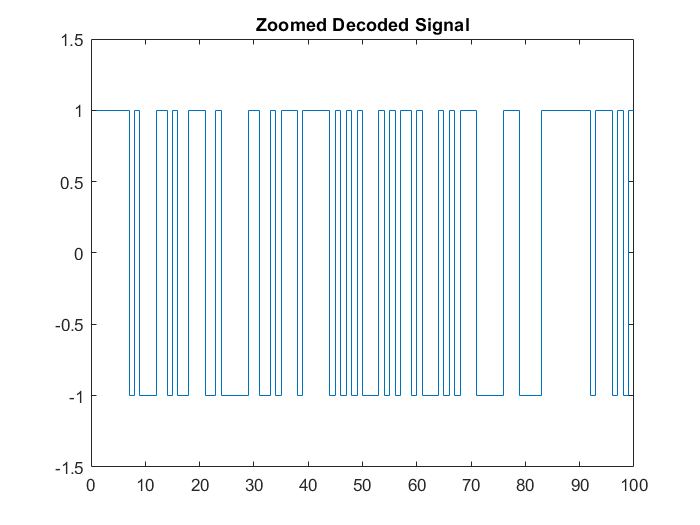


% plot the zoomed decoded signal
figure;
stairs([1:L], Y);
ylim([-1.5 1.5]);
xlim([0 100]);
title("Zoomed Decoded Signal")

## `Question 05`

`Repeat the above steps for a sequence of length ``L ``= 100``; ``000. Write a code to generate and plot the histogram of the received sequence taking the no of bins as 10. Compare your result with the one generated from the built-in function hist() of MATLAB. `

`    (a) Change the no of bins from 10 to 100 and observe the impact.   `

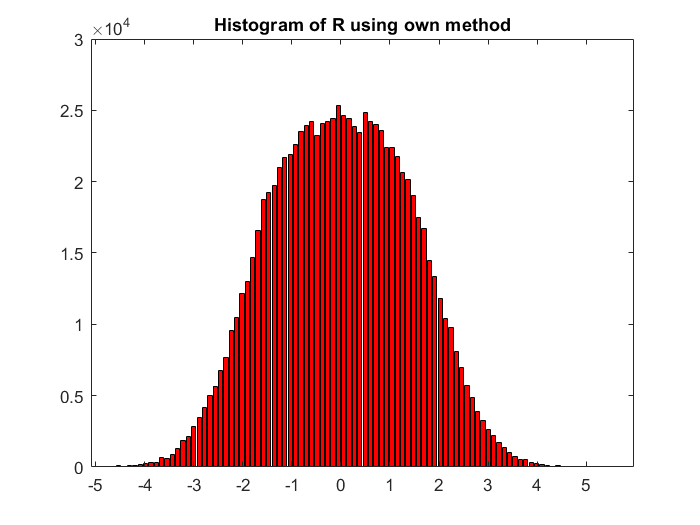


no_of_bins = 100; % this should be change to 100 for question 5(a) and for question 5 it should be equal to 10
mamimum_R = max(R); % determine the maximum amplitude value of received signal
minimum_R = min(R); % determine the minimum amplitude value of received signal
width = (mamimum_R-minimum_R)/(no_of_bins-1);  % determine the width of interval
center_of_interval = [minimum_R:width:mamimum_R]; % array of bin intervals


values_for_interval = zeros(1,no_of_bins); 
for index3 = 1:L
    for index4 = 1:no_of_bins
        if (R(index3) >= center_of_interval(index4) - width/2) && (R(index3) < center_of_interval(index4) + width/2) % check values within given interval
            values_for_interval(index4) = values_for_interval(index4) + 1; % add the count of availability within the interval
        end
    end
end

hist_vals = values_for_interval / width; % normalized the values

%plot the histogram
figure;
bar_graph1 = bar(center_of_interval,hist_vals);
set(bar_graph1,'FaceColor','red');
title("Histogram of R using own method");

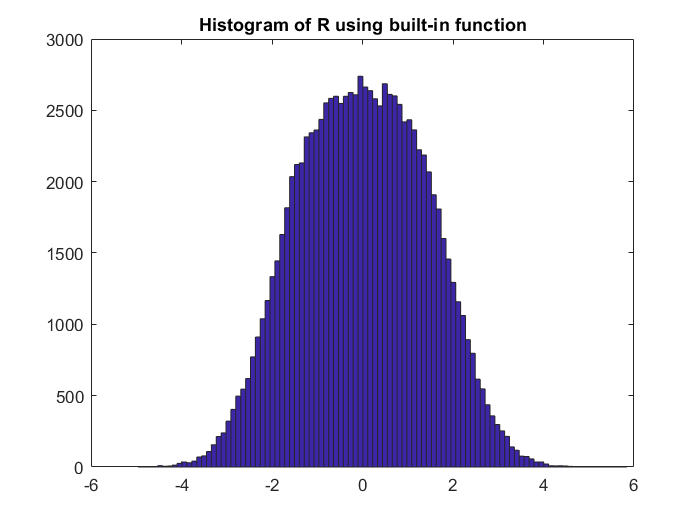

% plotting histogram using hist() built-in function
figure;
hist(R,no_of_bins);
title("Histogram of R using built-in function");

`keep no of bins as 100 for further calculations.`

## `Question 05`

`    (b) pdf of f_R|S(r|S=A) & histogram`

% determine the sequence for conditional pdf of f_R|S(r|S=A)

f_rS_One = []; % create a sequence for conditional pdf
i_1 = 1;

% fill the above array with Received signal values when Transmitted signal value equals to A (=1)
for index5 = 1:L 
    if S(index5) == A
        f_rS_One(i_1) = R(index5);
        i_1 = i_1 + 1;
    end
end

[counts1,centers1] = hist(f_rS_One, no_of_bins); % find histograms and centers for each interval

counts1 = counts1 / (length(f_rS_One)*width) % normalize over distribution

counts1 =     0.0002         0    0.0005    0.0005    0.0004    0.0002    0.0004    0.0009    0.0007    0.0013    0.0015    0.0024    0.0040    0.0053    0.0073    0.0079    0.0115    0.0126    0.0159    0.0180    0.0240    0.0279    0.0376    0.0414    0.0506    0.0620    0.0719    0.0792    0.0977    0.1070    0.1241    0.1397    0.1520    0.1677    0.2025    0.2178    0.2192    0.2454    0.2616    0.2724    0.2966    0.3057    0.3142    0.3232    0.3193    0.3226    0.3316    0.3299    0.3160    0.3026


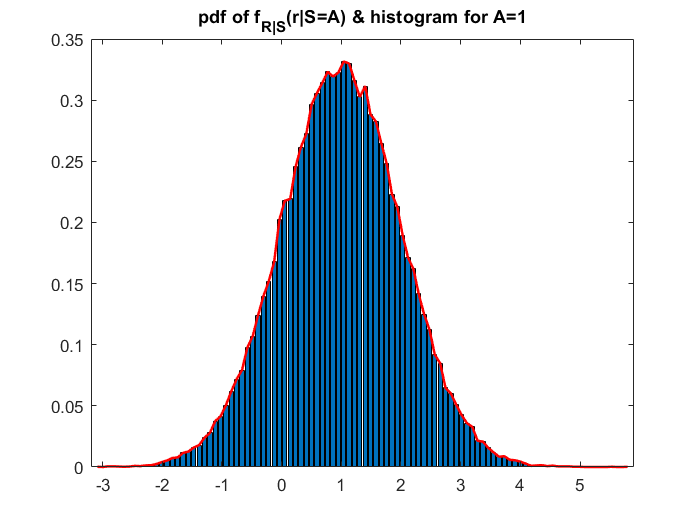


% plot the histogram and pdf on same figure
figure;
bar(centers1, counts1);
hold on;
figure2 = plot(centers1, counts1, 'r'); % plot the pdf
set(figure2,'linewidth',1.5);
title("pdf of f_{R|S}(r|S=A) & histogram for A=1");

% determine the sequence for conditional pdf of f_R|S(r|S=-A)

f_rS_minusOne = []; % create a sequence for conditional pdf
i_2 = 1;

% fill the above array with Received signal values when Transmitted signal value equals to -A (= -1)
for index6 = 1:L 
    if S(index6) == -1 * A
        f_rS_minusOne(i_2) = R(index6);
        i_2 = i_2 + 1;
    end
end

[counts2,centers2] = hist(f_rS_minusOne, no_of_bins); % find histograms and centers for each interval

counts2 = counts2 / (length(f_rS_minusOne)*width) % normalize over distribution

counts2 =     0.0002    0.0002    0.0005         0    0.0002    0.0013    0.0009    0.0007    0.0011    0.0015    0.0024    0.0033    0.0042    0.0049    0.0042    0.0057    0.0106    0.0084    0.0123    0.0154    0.0202    0.0260    0.0317    0.0326    0.0451    0.0471    0.0576    0.0709    0.0733    0.0816    0.0915    0.1048    0.1157    0.1421    0.1468    0.1565    0.1807    0.1850    0.1991    0.2143    0.2403    0.2590    0.2744    0.2713    0.2702    0.2847    0.2966    0.2856    0.2909    0.2777


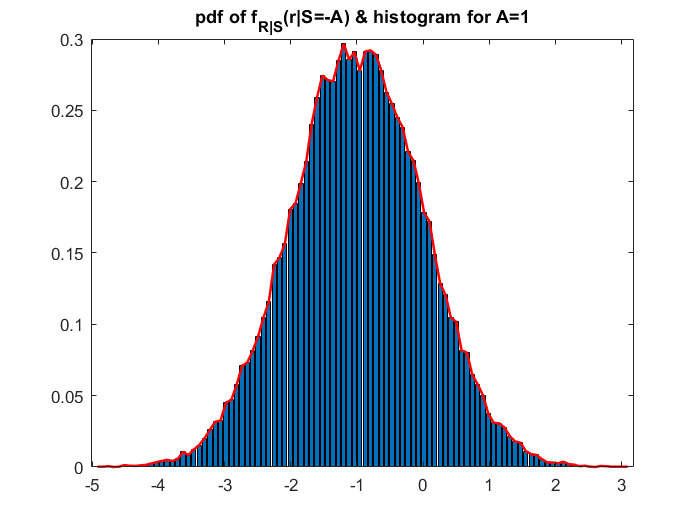


% plot the histogram and pdf on same figure
figure;
bar(centers2, counts2);
hold on;
figure2 = plot(centers2, counts2, 'r'); % plot the pdf
set(figure2,'linewidth',1.5);
title("pdf of f_{R|S}(r|S=-A) & histogram for A=1");

## `Question 05`

`    (c) Find E[R|S = A] ; E[R|S = -A] and E[R]  `

% determine E[R|S = A] using previously calculated PDFs

E_RS_A = 0; % initialize the value

for index7 = 1:no_of_bins
    E_RS_A = (centers1.*counts1)*width;  % finge the summation according to the definition of conditional expected value
end

val_E_RS_A = sum(E_RS_A);
val_E_RS_A

val_E_RS_A = 0.9979

% determine E[R|S = -A] using previously calculated PDFs

E_RS_minusA = 0; % initialize the value

for index7 = 1:no_of_bins
    E_RS_minusA = (centers2.*counts2)*width;  % finge the summation according to the definition of conditional expected value
end

val_E_RS_minusA = sum(E_RS_minusA);
val_E_RS_minusA

val_E_RS_minusA = -0.9910

% DEtermine E[R} using previously calculated PDFs

[counts3,centers3] = hist(R, no_of_bins); % find histograms and centers for each interval
counts3 = counts3 / (length(R)*width) % normalize over distribution

counts3 =     0.0001    0.0003    0.0001    0.0002    0.0009    0.0005    0.0006    0.0012    0.0023    0.0032    0.0027    0.0038    0.0064    0.0071    0.0100    0.0143    0.0196    0.0219    0.0295    0.0370    0.0456    0.0500    0.0568    0.0708    0.0835    0.0952    0.1070    0.1223    0.1324    0.1494    0.1665    0.1865    0.1943    0.1954    0.2121    0.2147    0.2165    0.2234    0.2339    0.2368    0.2382    0.2336    0.2382    0.2406    0.2391    0.2510    0.2442    0.2418    0.2365    0.2320



E_R = 0; % initialize the value

for index8 = 1:no_of_bins
    E_R = (centers3.*counts3)*width;  % finge the summation according to the definition of expected value
end

val_E_R = sum(E_R);
val_E_R

val_E_R = 0.0034

## `Question 05`

`    (d) Similarly, sketch the PDF f_R(r).`  

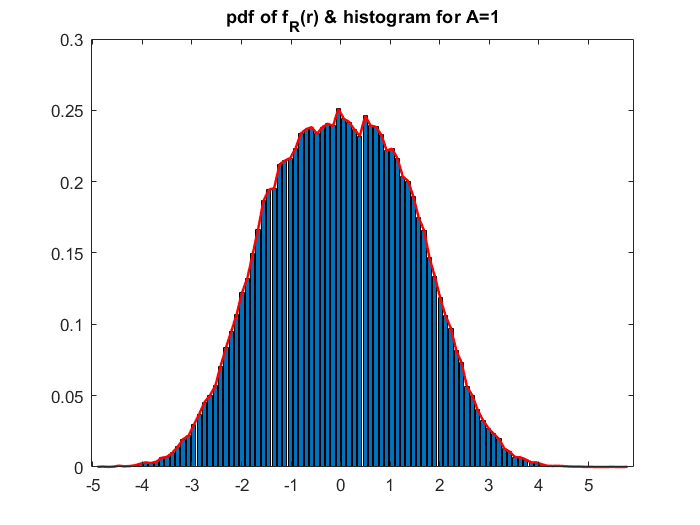

% plot the histogram and pdf on same figure
figure;
bar(centers3, counts3);
hold on;
figure3 = plot(centers3, counts3, 'r'); % plot the pdf
set(figure3,'linewidth',1.5);
title("pdf of f_{R}(r) & histogram for A=1");